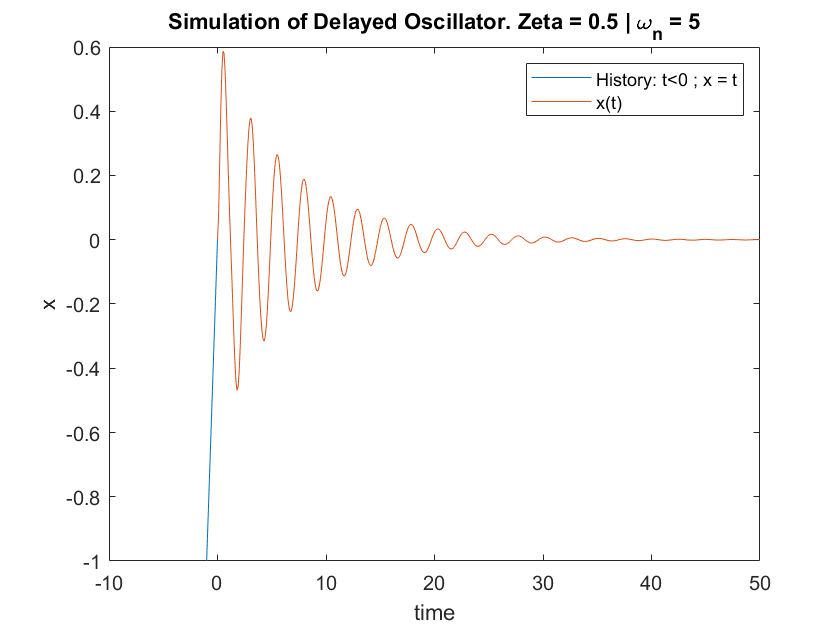

%HW3_Q2 Delayed Oscillator
clear all; close all;

%Parameters
tau = 1;
tstart = 0;
tdelta = 0.1;
tend = 50;
tspan = tstart:tdelta:tend;

%For plotting History
hist = tstart-tau:tdelta:tstart;
ic_1 = @(t)t;

%Initial Condition. Equivalent to y0 of ode45.
ic = @(t)[t 2*t];


%Parameters selection after studying the stability chart.
zeta = 0.5;
omega_n = 5;

%DDE setup
sol = dde23(@(t,y,ytau)ddefunc(t,y,ytau,zeta,omega_n),tau,ic,tspan);
y = deval(sol,tspan);

%Plotting
figure(1);box on; hold on;
plot(hist,ic_1(hist));
plot(tspan,y(1,:));
xlabel("time");
ylabel('x');
title("Simulation of Delayed Oscillator. Zeta = "+zeta+" | \omega_n = "+omega_n);
legend("History: t<0 ; x = t","x(t)");

function dydt = ddefunc(t,y,ytau,zeta,omega_n)
    dydt(1) = y(2);
    dydt(2) = -omega_n^2*y(1) - 2*zeta*omega_n*y(2) - (3/4)*omega_n^2*ytau(1);
    
    dydt = dydt';
end